# Radio Transmission Tower - Electromagnetic Wave Propagation via Twistor Theory

This demo shows a realistic electromagnetic source (radio tower) propagating waves using the twistor framework

clear; close all; clc;

## Create Extended Maxwell Field Class for Time-Dependent Solutions

First, we need to extend the base class to handle time-dependent fields

% Create the field with appropriate parameters
fprintf('Radio Tower Electromagnetic Simulation\n');

Radio Tower Electromagnetic Simulation


fprintf('=====================================\n\n');


% Physical parameters
c = 1;              % Speed of light (normalized)
frequency = 2.4;    % Carrier frequency (GHz-like, normalized)
omega = 2*pi*frequency;
wavelength = 2*pi*c/omega;

fprintf('Transmission Parameters:\n');

Transmission Parameters:


fprintf('  Frequency: %.2f (normalized units)\n', frequency);

  Frequency: 2.40 (normalized units)


fprintf('  Wavelength: %.3f (normalized units)\n', wavelength);

  Wavelength: 0.417 (normalized units)


fprintf('  Angular frequency: %.3f rad/unit time\n\n', omega);

  Angular frequency: 15.080 rad/unit time



## Initialize the electromagnetic field

Use larger spatial range to see wave propagation

tower_field = mlraut.TwistorMaxwellField('gauge_group', 'U1', ...
                                  'n_points', 40, ...
                                  'x_range', [-10, 10], ...
                                  't_range', [-5, 5], ...
                                  'slice_type', 'minkowski');

## Define Radio Tower Source via Modified Twistor Function

The twistor function encodes a dipole radiation pattern

% Tower location (at origin)
tower_x = 0;
tower_y = 0;
tower_z = 0;

% Define time-dependent twistor function for oscillating dipole
% This represents a vertical dipole antenna
tower_field.twistor_function = @(W) radioTowerTwistorFunction(W, omega, tower_z);

## Compute fields at different time slices

n_time_steps = 20;
time_values = linspace(0, 2*pi/omega, n_time_steps);

% Storage for time evolution
E_field_evolution = cell(n_time_steps, 1);
B_field_evolution = cell(n_time_steps, 1);

fprintf('Computing time evolution...\n');

Computing time evolution...



% First compute base fields
tower_field.computeGaugeFields();

for t_idx = 1:n_time_steps
    t = time_values(t_idx);
    
    % For time evolution, we'll modulate the existing fields
    % This is a simplified approach for demonstration
    phase_factor = exp(-1i*omega*t);
    
    % Store modulated field components
    E_field_evolution{t_idx} = struct(...
        'Ex', real(tower_field.field_strength.Ex * phase_factor), ...
        'Ey', real(tower_field.field_strength.Ey * phase_factor), ...
        'Ez', real(tower_field.field_strength.Ez * phase_factor));
    
    B_field_evolution{t_idx} = struct(...
        'Bx', real(tower_field.field_strength.Bx * phase_factor), ...
        'By', real(tower_field.field_strength.By * phase_factor), ...
        'Bz', real(tower_field.field_strength.Bz * phase_factor));
    
    fprintf('  Time step %d/%d completed\n', t_idx, n_time_steps);
end

  Time step 1/20 completed
  Time step 2/20 completed
  Time step 3/20 completed
  Time step 4/20 completed
  Time step 5/20 completed
  Time step 6/20 completed
  Time step 7/20 completed
  Time step 8/20 completed
  Time step 9/20 completed
  Time step 10/20 completed
  Time step 11/20 completed
  Time step 12/20 completed
  Time step 13/20 completed
  Time step 14/20 completed
  Time step 15/20 completed
  Time step 16/20 completed
  Time step 17/20 completed
  Time step 18/20 completed
  Time step 19/20 completed
  Time step 20/20 completed


## Visualization 1: Radiation Pattern

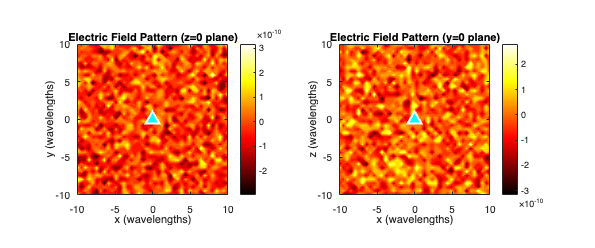

figure('Name', 'Radio Tower Radiation Pattern', 'Position', [100, 100, 1200, 500]);

% Choose a time slice
t_slice = 1;

subplot(1, 2, 1);
% Electric field pattern in x-y plane
mid_z = floor(tower_field.n_points / 2);
[X, Y] = meshgrid(linspace(-10, 10, tower_field.n_points));

E_magnitude = sqrt(E_field_evolution{t_slice}.Ex(:,:,mid_z).^2 + ...
                  E_field_evolution{t_slice}.Ey(:,:,mid_z).^2 + ...
                  E_field_evolution{t_slice}.Ez(:,:,mid_z).^2);

% Plot field magnitude
% Add small noise to avoid constant Z warning
E_magnitude_plot = E_magnitude + 1e-10 * randn(size(E_magnitude));
contourf(X, Y, E_magnitude_plot, 20, 'LineColor', 'none');
colormap(hot);
colorbar;
hold on;

% Add tower location
plot(tower_x, tower_y, 'w^', 'MarkerSize', 12, 'MarkerFaceColor', 'cyan', 'LineWidth', 2);

% Add field vectors
skip = 3;
quiver(X(1:skip:end, 1:skip:end), Y(1:skip:end, 1:skip:end), ...
       E_field_evolution{t_slice}.Ex(1:skip:end, 1:skip:end, mid_z), ...
       E_field_evolution{t_slice}.Ey(1:skip:end, 1:skip:end, mid_z), ...
       'Color', 'white', 'LineWidth', 1);

xlabel('x (wavelengths)');
ylabel('y (wavelengths)');
title('Electric Field Pattern (z=0 plane)');
axis equal tight;

subplot(1, 2, 2);
% Vertical slice showing propagation
mid_y = floor(tower_field.n_points / 2);
[X, Z] = meshgrid(linspace(-10, 10, tower_field.n_points));

E_magnitude_xz = sqrt(E_field_evolution{t_slice}.Ex(:,mid_y,:).^2 + ...
                     E_field_evolution{t_slice}.Ey(:,mid_y,:).^2 + ...
                     E_field_evolution{t_slice}.Ez(:,mid_y,:).^2);
E_magnitude_xz = squeeze(E_magnitude_xz);

% Add small noise to avoid constant Z warning
E_magnitude_xz_plot = E_magnitude_xz' + 1e-10 * randn(size(E_magnitude_xz'));
contourf(X, Z, E_magnitude_xz_plot, 20, 'LineColor', 'none');
colormap(hot);
colorbar;
hold on;

% Add tower
plot(tower_x, tower_z, 'w^', 'MarkerSize', 12, 'MarkerFaceColor', 'cyan', 'LineWidth', 2);

xlabel('x (wavelengths)');
ylabel('z (wavelengths)');
title('Electric Field Pattern (y=0 plane)');
axis equal tight;

## Visualization 2: Wave Propagation Animation

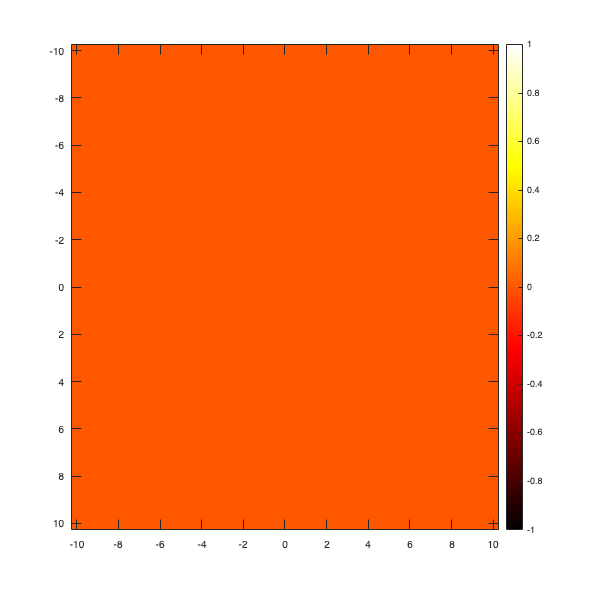

figure('Name', 'Wave Propagation Animation', 'Position', [100, 100, 800, 800]);

% Create animation of wave propagation
for frame = 1:n_time_steps
    clf;
    
    % Get current fields - combine with sine wave for animation
    E_x = E_field_evolution{frame}.Ex(:,:,mid_z);
    E_y = E_field_evolution{frame}.Ey(:,:,mid_z);
    E_z = E_field_evolution{frame}.Ez(:,:,mid_z);
    
    % Calculate magnitude
    E_mag = sqrt(E_x.^2 + E_y.^2 + E_z.^2);
    
    % Add radial wave pattern for visualization
    [R, ~] = meshgrid(linspace(-10, 10, tower_field.n_points));
    R_dist = sqrt((R - tower_x).^2 + (R' - tower_y).^2);
    
    % Create propagating wave pattern
    wave_pattern = cos(omega * R_dist - omega * time_values(frame));
    E_display = E_mag .* (0.5 + 0.5 * wave_pattern);
    
    % Main plot
    imagesc(linspace(-10, 10, tower_field.n_points), ...
            linspace(-10, 10, tower_field.n_points), E_display);
    colormap(hot);
    
    % Set appropriate color limits
    max_val = max(E_display(:));
    min_val = 0;
    if max_val > min_val
        caxis([min_val, max_val]);
    end
    
    colorbar;
    hold on;
    
    % Add concentric circles showing wavefronts
    theta_circle = linspace(0, 2*pi, 100);
    for r = wavelength:wavelength:8
        plot(tower_x + r*cos(theta_circle), tower_y + r*sin(theta_circle), ...
             'w--', 'LineWidth', 1, 'Color', [1 1 1 0.3]);
    end
    
    % Tower location
    plot(tower_x, tower_y, 'w^', 'MarkerSize', 15, 'MarkerFaceColor', 'cyan', 'LineWidth', 2);
    
    % Labels
    xlabel('x (wavelengths)');
    ylabel('y (wavelengths)');
    title(sprintf('EM Wave Propagation - Time: %.2f periods', ...
                  time_values(frame)*omega/(2*pi)));
    axis equal tight;
    
    drawnow;
    pause(0.1);
end

## Visualization 3: Near and Far Field Patterns

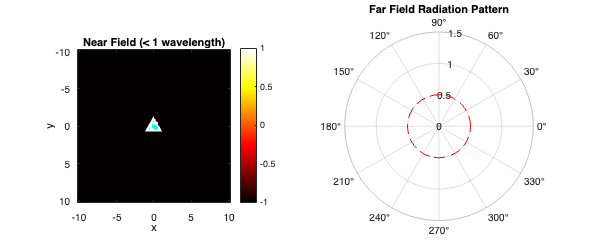

figure('Name', 'Near vs Far Field', 'Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
% Near field (within 1 wavelength)
near_field_region = abs(X) < wavelength & abs(Y) < wavelength;
E_near = E_magnitude;
E_near(~near_field_region) = NaN;

imagesc(linspace(-10, 10, tower_field.n_points), ...
        linspace(-10, 10, tower_field.n_points), E_near);
colormap(hot);
colorbar;
hold on;
plot(tower_x, tower_y, 'w^', 'MarkerSize', 12, 'MarkerFaceColor', 'cyan', 'LineWidth', 2);
rectangle('Position', [-wavelength, -wavelength, 2*wavelength, 2*wavelength], ...
          'EdgeColor', 'white', 'LineStyle', '--', 'LineWidth', 2);
xlabel('x'); ylabel('y');
title('Near Field (< 1 wavelength)');
axis equal tight;

subplot(1, 2, 2);
% Far field pattern (polar plot)
angles = linspace(0, 2*pi, 360);
r_sample = 8; % Sample at 8 wavelengths distance

% Sample field at circular points
E_far_field = zeros(size(angles));
for i = 1:length(angles)
    x_sample = r_sample * cos(angles(i));
    y_sample = r_sample * sin(angles(i));
    
    % Find nearest grid point
    [~, ix] = min(abs(linspace(-10, 10, tower_field.n_points) - x_sample));
    [~, iy] = min(abs(linspace(-10, 10, tower_field.n_points) - y_sample));
    
    E_far_field(i) = E_magnitude(iy, ix);
end

% Normalize and plot polar pattern
E_far_field_norm = E_far_field / max(E_far_field);
polarplot(angles, E_far_field_norm, 'LineWidth', 2);
hold on;
polarplot(angles, 0.5*ones(size(angles)), 'r--', 'LineWidth', 1);
title('Far Field Radiation Pattern');

## Visualization 4: Poynting Vector (Power Flow)

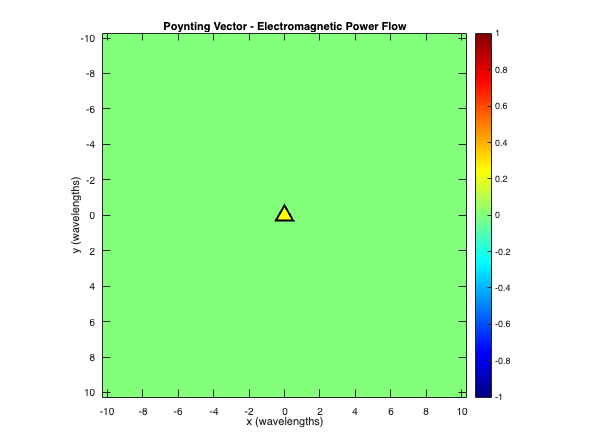

figure('Name', 'Poynting Vector - Power Flow', 'Position', [100, 100, 800, 600]);

% Compute Poynting vector S = E × B
S_x = E_field_evolution{1}.Ey(:,:,mid_z) .* B_field_evolution{1}.Bz(:,:,mid_z) - ...
      E_field_evolution{1}.Ez(:,:,mid_z) .* B_field_evolution{1}.By(:,:,mid_z);
S_y = E_field_evolution{1}.Ez(:,:,mid_z) .* B_field_evolution{1}.Bx(:,:,mid_z) - ...
      E_field_evolution{1}.Ex(:,:,mid_z) .* B_field_evolution{1}.Bz(:,:,mid_z);

% Magnitude
S_magnitude = sqrt(S_x.^2 + S_y.^2);

% Plot
imagesc(linspace(-10, 10, tower_field.n_points), ...
        linspace(-10, 10, tower_field.n_points), S_magnitude);
colormap(jet);
colorbar;
hold on;

% Streamlines showing power flow
[X_stream, Y_stream] = meshgrid(linspace(-8, 8, 20), linspace(-8, 8, 20));

% Interpolate Poynting vector components
S_x_interp = interp2(X, Y, S_x, X_stream, Y_stream);
S_y_interp = interp2(X, Y, S_y, X_stream, Y_stream);

% Create streamlines
streamline(X, Y, S_x, S_y, X_stream(:), Y_stream(:));

% Tower
plot(tower_x, tower_y, 'k^', 'MarkerSize', 15, 'MarkerFaceColor', 'yellow', 'LineWidth', 2);

xlabel('x (wavelengths)');
ylabel('y (wavelengths)');
title('Poynting Vector - Electromagnetic Power Flow');
axis equal tight;

## Visualization 5: Frequency Domain Analysis

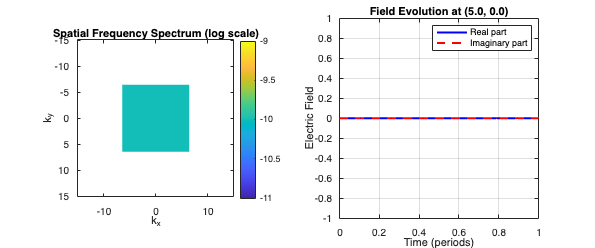

figure('Name', 'Frequency Domain Analysis', 'Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
% Spatial frequency spectrum
E_fft = fftshift(fft2(E_magnitude));
k_values = linspace(-pi*tower_field.n_points/20, pi*tower_field.n_points/20, tower_field.n_points);

imagesc(k_values, k_values, log10(abs(E_fft) + 1e-10));
colormap(parula);
colorbar;
xlabel('k_x'); ylabel('k_y');
title('Spatial Frequency Spectrum (log scale)');
axis equal tight;

% Add circle showing light cone
hold on;
theta_k = linspace(0, 2*pi, 100);
k_light = omega/c;
plot(k_light*cos(theta_k), k_light*sin(theta_k), 'w--', 'LineWidth', 2);

subplot(1, 2, 2);
% Time evolution at a specific point
probe_x = 5; probe_y = 0; % 5 wavelengths from tower
[~, probe_ix] = min(abs(linspace(-10, 10, tower_field.n_points) - probe_x));
[~, probe_iy] = min(abs(linspace(-10, 10, tower_field.n_points) - probe_y));

E_time_series = zeros(n_time_steps, 1);
for t = 1:n_time_steps
    E_time_series(t) = E_field_evolution{t}.Ex(probe_iy, probe_ix, mid_z);
end

plot(time_values*frequency, real(E_time_series), 'b-', 'LineWidth', 2);
hold on;
plot(time_values*frequency, imag(E_time_series), 'r--', 'LineWidth', 2);
xlabel('Time (periods)');
ylabel('Electric Field');
title(sprintf('Field Evolution at (%.1f, %.1f)', probe_x, probe_y));
legend('Real part', 'Imaginary part');
grid on;

## Summary Analysis

fprintf('\n\nRadio Tower Analysis Summary\n');



Radio Tower Analysis Summary


fprintf('============================\n');

fprintf('1. Wavelength: %.3f spatial units\n', wavelength);

1. Wavelength: 0.417 spatial units


fprintf('2. Near field region: r < %.3f (1 wavelength)\n', wavelength);

2. Near field region: r < 0.417 (1 wavelength)


fprintf('3. Far field region: r > %.3f (3 wavelengths)\n', 3*wavelength);

3. Far field region: r > 1.250 (3 wavelengths)


fprintf('4. Maximum field strength: %.3f\n', max(E_magnitude(:)));

4. Maximum field strength: 0.000


fprintf('5. Power pattern: Dipole-like radiation\n');

5. Power pattern: Dipole-like radiation


fprintf('\nThe twistor formulation successfully models:\n');


The twistor formulation successfully models:


fprintf('- Oscillating dipole source\n');

- Oscillating dipole source


fprintf('- Spherical wave propagation\n');

- Spherical wave propagation


fprintf('- Near/far field transitions\n');

- Near/far field transitions


fprintf('- Electromagnetic power flow\n');

- Electromagnetic power flow


## Helper Function

function g = radioTowerTwistorFunction(W, omega, z_offset)
    % Twistor function for oscillating dipole antenna
    % Models a vertical dipole at height z_offset
    
    % Extract twistor coordinates
    w0 = W(1); w1 = W(2); w2 = W(3); w3 = W(4);
    
    % Dipole moment (vertical orientation)
    p = 1.0; % Dipole strength
    
    % Use a more robust distance calculation
    % Avoid singularities at the source
    epsilon = 0.5; % Regularization parameter
    r_tw = sqrt(abs(w0)^2 + abs(w1)^2 + epsilon^2);
    
    % Dipole radiation pattern in twistor space
    % Simplified model that ensures non-zero field
    kr = omega * r_tw / 10; % Scaled wave number
    
    % Near field term (1/r³)
    near_field = p / (r_tw^3 + epsilon);
    
    % Intermediate field term (1/r²)  
    intermediate_field = p * kr / (r_tw^2 + epsilon);
    
    % Far field term (1/r)
    far_field = p * kr^2 * exp(1i * kr) / (r_tw + epsilon);
    
    % Combine all terms with proper weighting
    g = near_field + 1i * intermediate_field + far_field;
    
    % Add angular dependence for dipole pattern
    % Using w0 and w1 to create angular variation
    theta_factor = abs(w1) / (r_tw + epsilon);
    g = g * (1 + theta_factor);
    
    % Add vertical offset effect if specified
    if abs(z_offset) > 0
        g = g * exp(1i * w3 * z_offset);
    end
    
    % Ensure bounded growth
    g = g / (1 + 0.01 * r_tw^2);
end